a)

n_keys=10;
tamanho_array=1000;

posicoes_do_array=randi(tamanho_array,n_keys,10000);
matriz=zeros(1,10000);
for l = 1:10000
    [x,y]=size(unique(posicoes_do_array(:,l)));
    matriz(l)=x<n_keys;
end

probabilidade_pelo_menos_1_colisao=sum(matriz)/10000

probabilidade_pelo_menos_1_colisao = 0.0432

b)

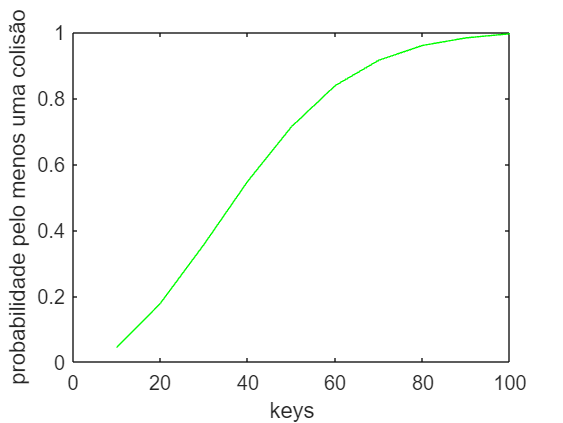

n_keys=0;
tamanho_array=1000;
matriz_probabilidades=zeros(1,10);
for h=1:10
    n_keys=n_keys+10;
    posicoes_do_array=randi(tamanho_array,n_keys,10000);
    matriz=zeros(1,10000);
    for l = 1:10000
        [x,y]=size(unique(posicoes_do_array(:,l)));
        matriz(l)=x<n_keys;
    end
    
    probabilidade_pelo_menos_1_colisao=sum(matriz)/10000;

    matriz_probabilidades(h)=probabilidade_pelo_menos_1_colisao;

end


plot(10:10:100,matriz_probabilidades,"green")

xlabel('keys')
ylabel('probabilidade pelo menos uma colisão')

c)

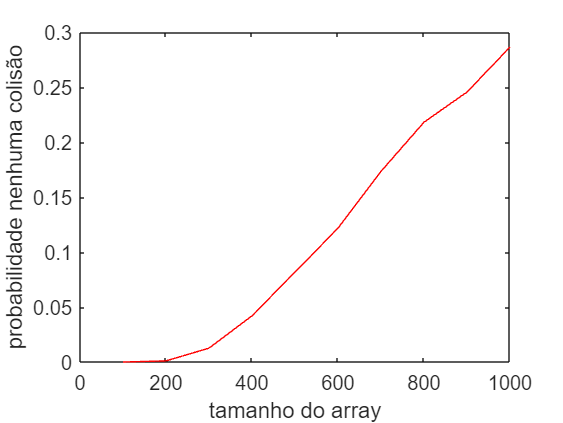

n_keys=50;
tamanho_array=0;
matriz_probabilidades=zeros(1,10);
for h=1:10
    tamanho_array=tamanho_array+100;
    posicoes_do_array=randi(tamanho_array,n_keys,10000);
    matriz=zeros(1,10000);
    for l = 1:10000
        [x,y]=size(unique(posicoes_do_array(:,l)));
        matriz(l)=x==n_keys;
    end
    
    probabilidade_nehuma_colisao=sum(matriz)/10000;

    matriz_probabilidades(h)=probabilidade_nehuma_colisao;

end


plot(100:100:1000,matriz_probabilidades,"red")

xlabel('tamanho do array')
ylabel('probabilidade nenhuma colisão')